IAE = 137.4511			P = 20		I = 0		D = 0
IAE = 256.024			P = 32.2159		I = 1.5812		D = 0.92395
IAE = 263.0211			P = 2.3004		I = 0.33742		D = 7.6611
IAE = 254.3612			P = 7.5392		I = 1.1055		D = 2.6844
IAE = 256.9212			P = 11.189		I = 1.4679		D = 2.5463
IAE = 269.0839			P = 30.1246		I = 3.1887		D = 5.3468
IAE = 236.5998			P = 16.2735		I = 0.0473		D = 1.1743
IAE = 254.3656			P = 12.7423		I = 0.91876		D = 2.224
IAE = 267.1034			P = 17.5487		I = 2.7483		D = 5.2753
IAE = 262.8038			P = 14.0208		I = 0.14672		D = 4.3378
IAE = 262.047			P = 18.4376		I = 3.1454		D = 2.2728
IAE = 266.6808			P = 16.494		I = 2.6439		D = 7.8096
IAE = 271.5941			P = 37.8854		I = 3.0204		D = 4.5966
IAE = 269.8237			P = 37.9161		I = 2.0706		D = 5.8176
IAE = 268.6147			P = 18.4228		I = 3.9613		D = 7.0345
IAE = 263.8054			P = 14.8137		I = 0.71173		D = 5.2967
IAE = 265.6875			P = 13.4758		I = 1.7481		D = 4.1744
IAE = 259.2777			P = 19.5426		I = 2.5223		D = 2.0381
IAE = 269.5014			P = 34.0627		I = 2.6945		D = 5.3894
IAE = 286.

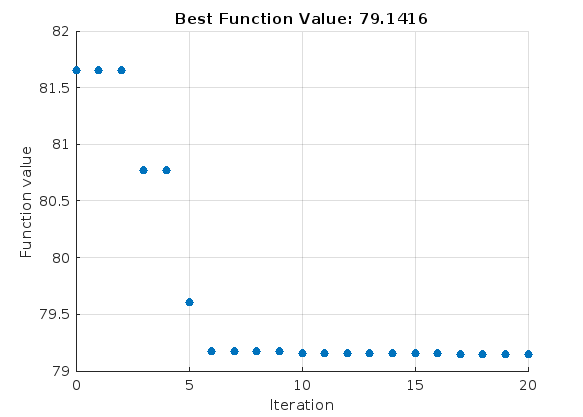

% Set nondefault solver options
options2 = optimoptions("particleswarm","InitialPoints",K_start,...
    "InertiaRange",Inertia_range,"SelfAdjustmentWeight",2,...
    "SocialAdjustmentWeight",2,"MaxIterations",20,"MaxStallIterations",10,...
    "Display","iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options2);


% Clear variables
clearvars options2